## Polar Overturning Conceptual Model

#### Live script to run experiments for LGM and HS1 and produce figures for collaboration with Patrick Blaser. Includes stable isotope calculation and internal conversion fluxes.

#### twnh Sep '21, Nov '22, May '23, Oct '23

Based on `run_POC_model.mlx` from H21.

Must cd to the working directory to run the notebook. The notebook writes pdf figures to the figures directory.

Housekeeping:

clear
clear plot_POC_TS_diagram  % Clears persistent variables from this function.
close all
clc
if(isempty(gcp))
    parpool('local',96) 
end

Exp G1: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM).

modelG1 = build_POC_model('NH_FSBSO_LGM_can') ;

 Solutions for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             1.5000          |           36.0500          |   4.4272   4.5250   4.5560
 Polar    Water:                     -1.9481          |           35.7064          |  -0.3128  -0.1229  -0.0100
 Overflow Water:            -1.9693  -1.9174  -1.8613 |  36.0681  36.0739  36.0864 |  -4.7239  -4.6132  -4.4256
 Shelf    Water:            -1.9693  -1.9698  -1.9708 |  36.0689  36.0771  36.0934 |  -4.5392  -4.5095  

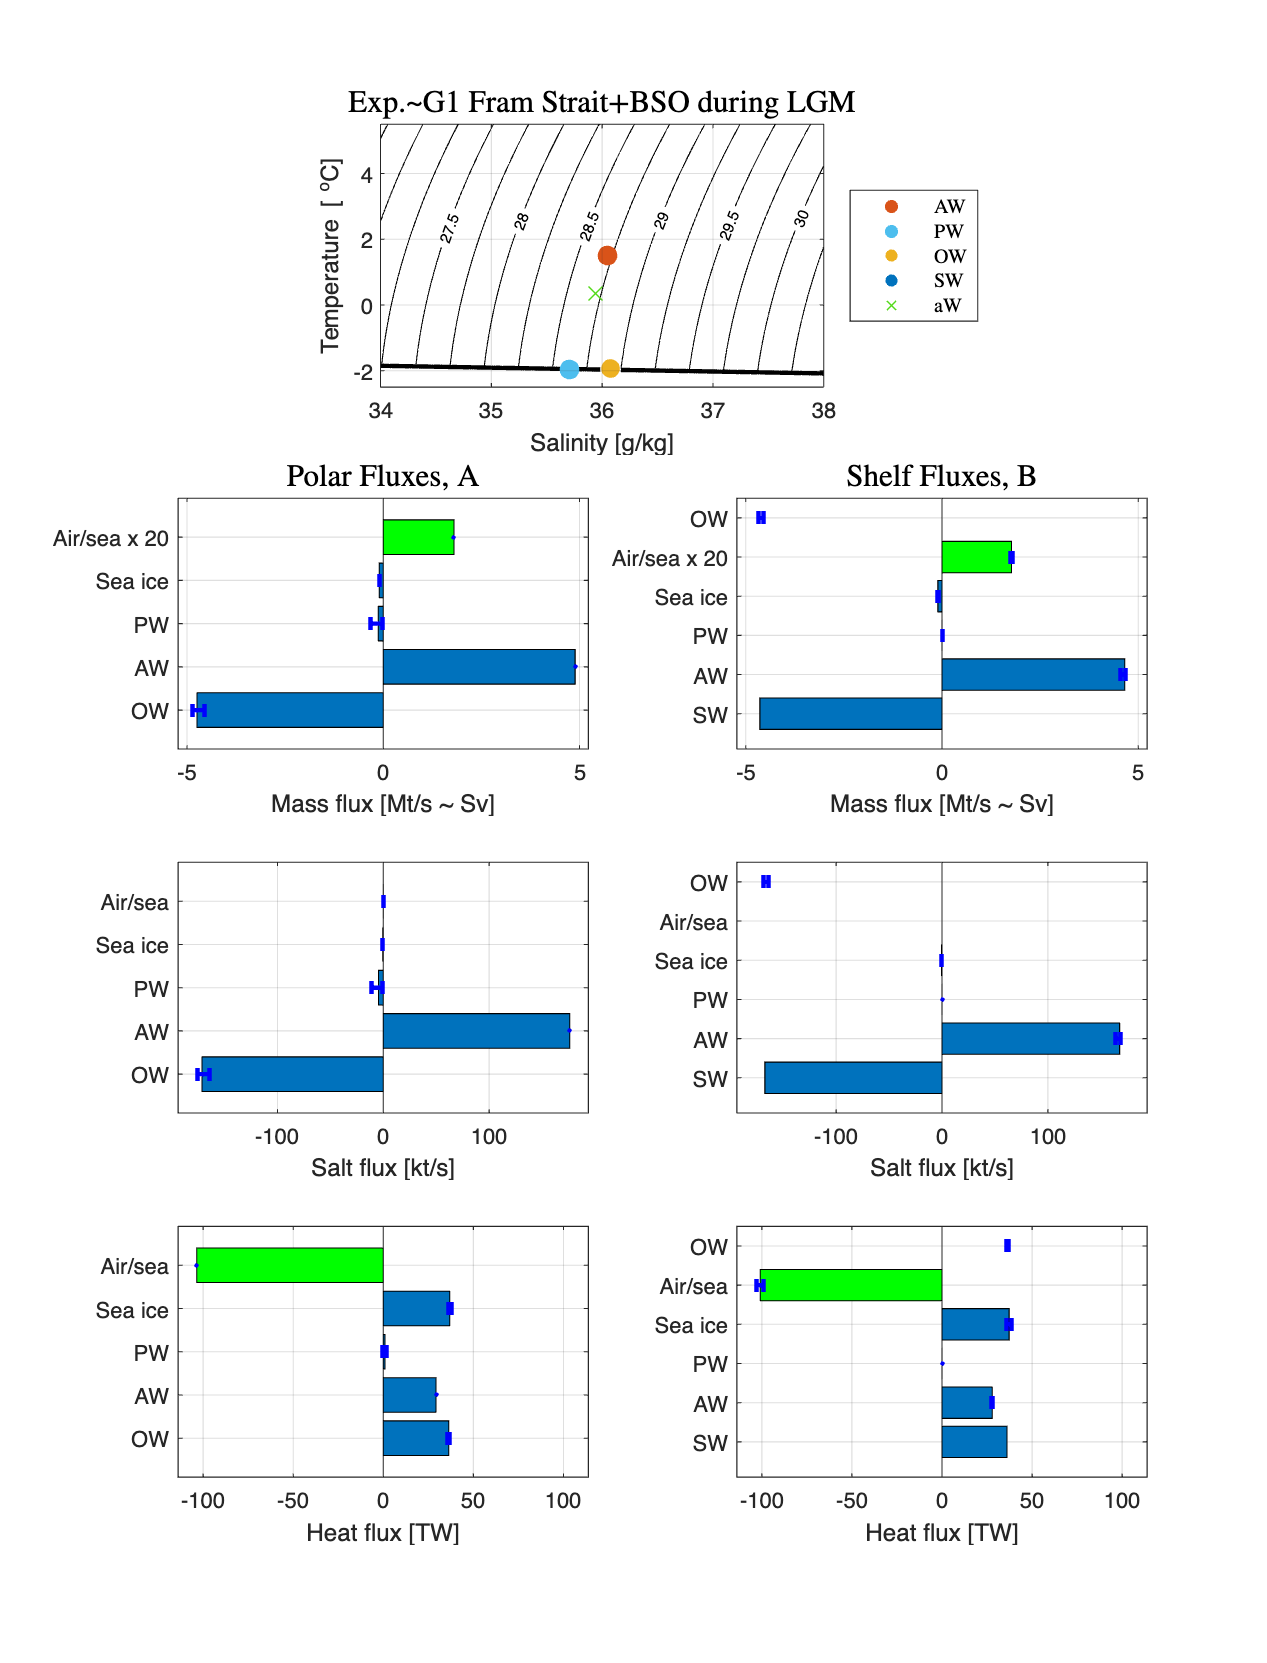

plot_POC_solution(modelG1)

modelG1 = build_stable_isotope_model(modelG1) ;


 Internal fluxes for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:
 AW  -> PW  flux:            0.1599 to   0.1599 Sv
 AW  -> OW  flux:            0.0715 to   0.0715 Sv
 SW  -> ice flux:            0.1043 to   0.1043 Sv
 ice -> PW  flux:            0.0009 to   0.0009 Sv
 PW  -> OW  flux:            0.0352 to   0.0352 Sv

 Shelf FW   flux:           -0.0892 to  -0.0892 Sv
 Basin FW   flux:           -0.0008 to  -0.0008 Sv

 Of [1] solutions to the original model, [1] give physical internal fluxes.

 Stable isotope solutions for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic

Exp G1b: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with warm AW.

modelG1b = build_POC_model('NH_FSBSO_LGM_hiT1') ;

 Solutions for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      4.0000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             4.0000          |           36.0500          |   0.8089   1.3741   2.2538
 Polar    Water:                     -1.9189          |           35.2049          |  -3.2392  -2.0747  -0.0101
 Overflow Water:            -0.0265   0.0374   0.1891 |  35.7822  35.8431  35.9223 |  -4.7471  -2.7369  -1.5988
 Shelf    Water:            -1.9532  -1.9603  -1.9711 |  35.7925  35.9147  36.0980 |  -2.

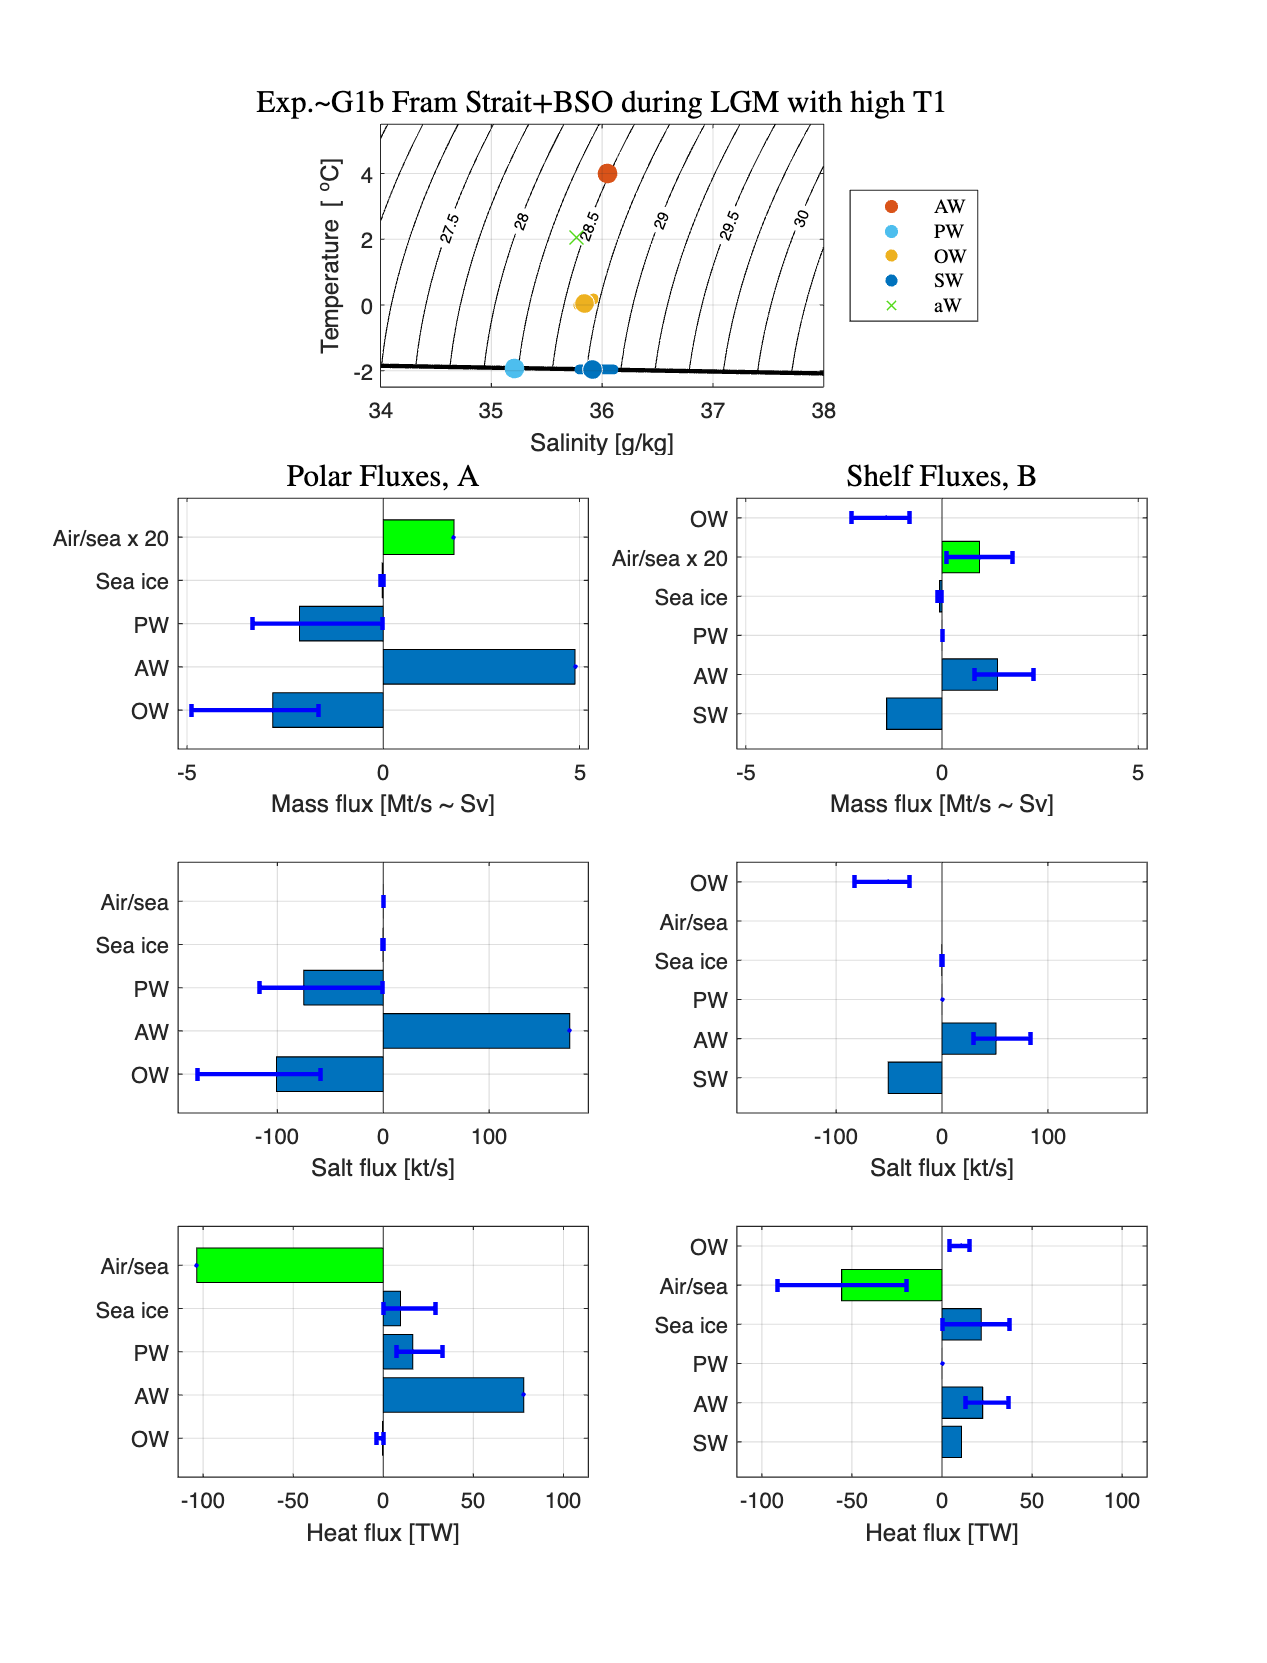

plot_POC_solution(modelG1b)

modelG1b = build_stable_isotope_model(modelG1b) ;


 Internal fluxes for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:
 AW  -> PW  flux:            2.5317 to   2.5317 Sv
 AW  -> OW  flux:            0.9404 to   0.9404 Sv
 SW  -> ice flux:            0.0610 to   0.0610 Sv
 ice -> PW  flux:            0.0342 to   0.0342 Sv
 PW  -> OW  flux:            0.4632 to   0.4632 Sv

 Shelf FW   flux:           -0.0596 to  -0.0596 Sv
 Basin FW   flux:           -0.0304 to  -0.0304 Sv

 Of [1] solutions to the original model, [1] give physical internal fluxes.

 Stable isotope solutions for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
---------------------------------------------------------------------

Exp G2: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with lower Q

modelG2 = build_POC_model('NH_FSBSO_LGM_lowQ') ;

 Solutions for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             1.5000          |           36.0500          |   2.1685   2.6530   3.1441
 Polar    Water:                     -1.9481          |           35.7064          |  -2.6066  -1.4686  -0.0094
 Overflow Water:            -1.9648  -1.5120  -1.1528 |  35.9907  36.0560  36.1283 |  -4.7172  -3.2852  -2.1643
 Shelf    Water:            -1.9648  -1.9703  -1.9789 |  35.9913  36.0852  36.2323 |  -3.116

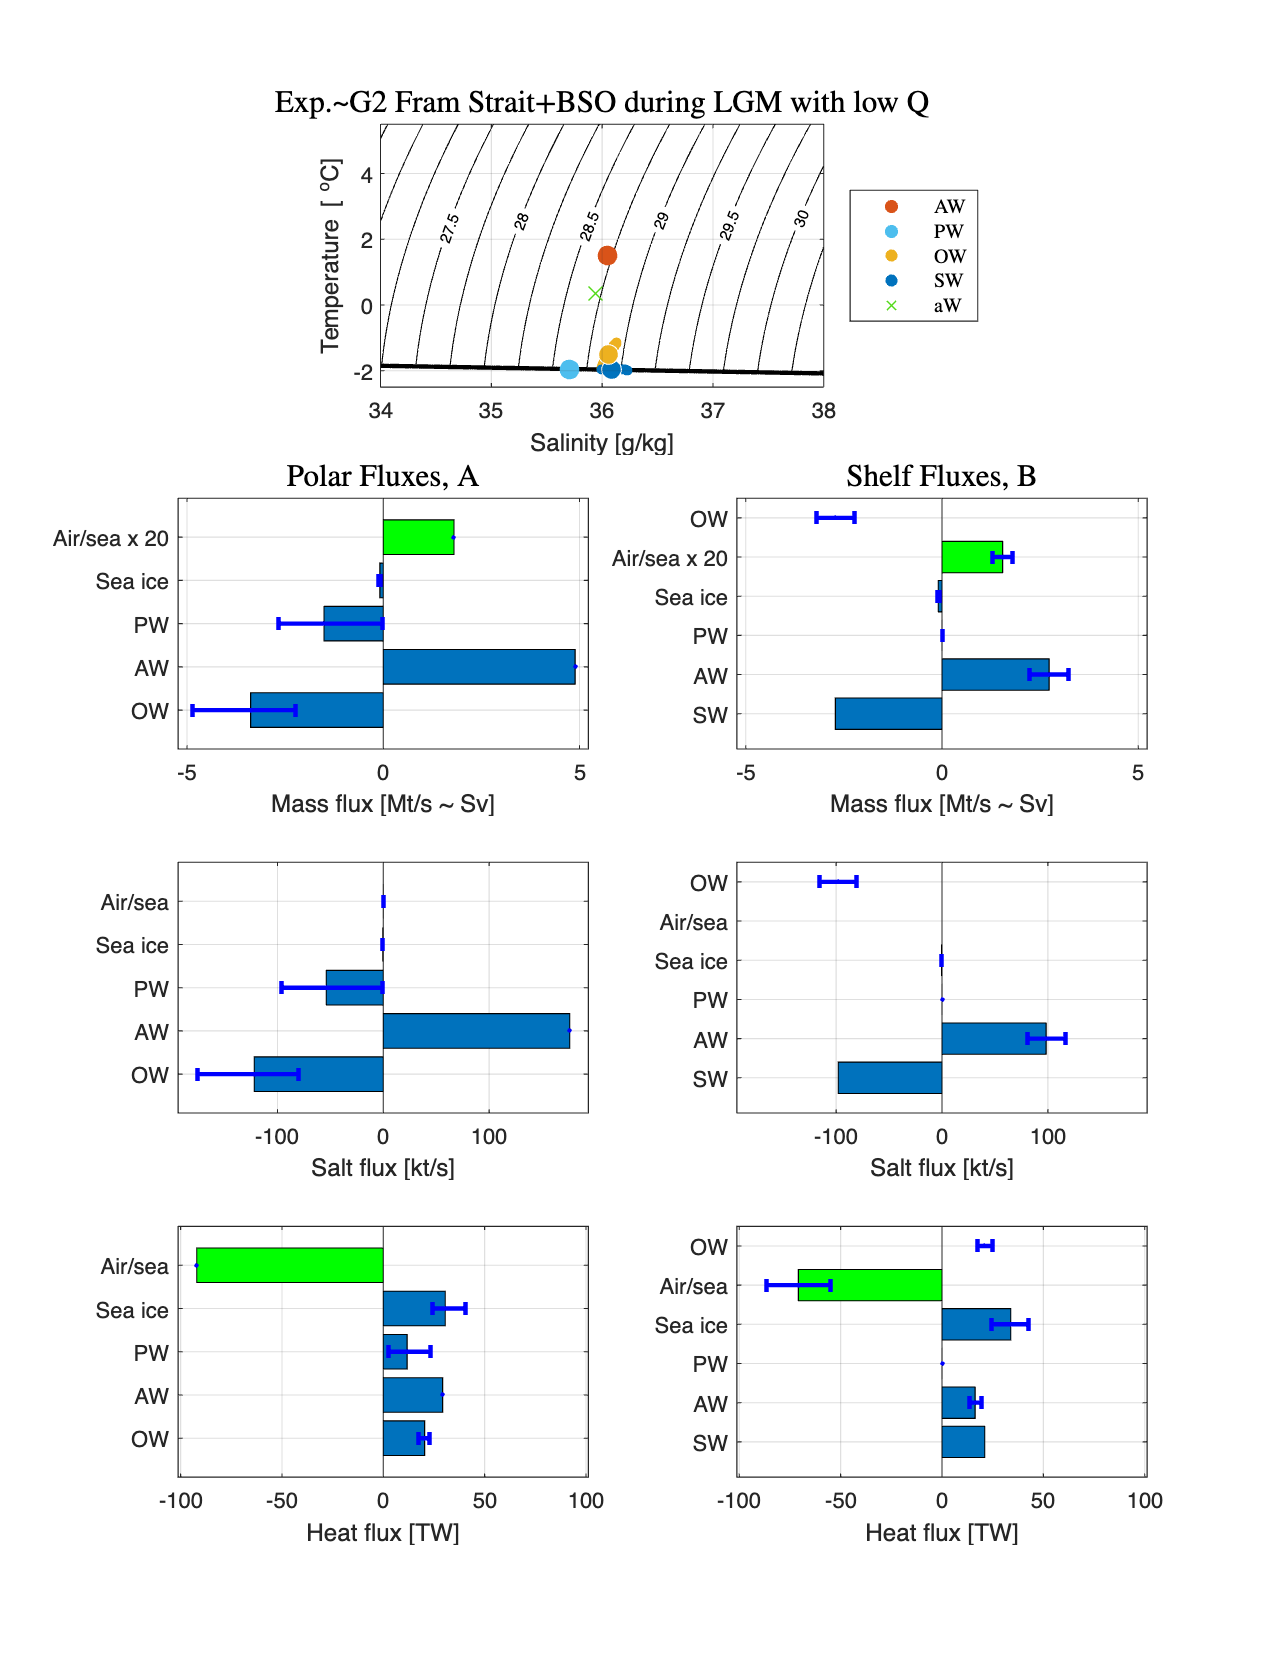

plot_POC_solution(modelG2)

modelG2 = build_stable_isotope_model(modelG2) ;


 Internal fluxes for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:
 AW  -> PW  flux:            1.7123 to   1.7123 Sv
 AW  -> OW  flux:            0.4450 to   0.4450 Sv
 SW  -> ice flux:            0.0949 to   0.0949 Sv
 ice -> PW  flux:            0.0093 to   0.0093 Sv
 PW  -> OW  flux:            0.2192 to   0.2192 Sv

 Shelf FW   flux:           -0.0818 to  -0.0818 Sv
 Basin FW   flux:           -0.0082 to  -0.0082 Sv

 Of [1] solutions to the original model, [1] give physical internal fluxes.

 Stable isotope solutions for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
---------------------------------------------------------------------------

Exp G3: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values. Exp G4 repeats this one but with more resolution in parameters.

modelG3 = build_POC_model('NH_LGM_range_small') ;

 Solutions for experiment: [Exp.~G3 Arctic LGM sensitivity wrt Expt.~G1] with file suffices: [NH_LGM_range_small]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             1.5000   1.5000   1.5000 |  36.0500  36.0500  36.0500 |   0.5938   5.0469   9.5000
 Atlantic Water to shelf:    1.5000   1.5000   1.5000 |  36.0500  36.0500  36.0500 |   0.0007   2.8828   9.4527
 Polar    Water:            -1.9481  -1.9481  -1.9481 |  35.7064  35.7064  35.7064 |  -5.8712  -1.5903  -0.0000
 Overflow Water:            -1.9759  -0.8696   0.3522 |  35.8228  36.1284  36.3651 |  -9.4508  -4.9106  -0.0000
 Shelf    Water:            -1.9548  -2.0138  -2.2015 |  35.8196  36.8269  40.0000 |

plot_POC_solutions2(modelG3,modelG1,modelG1,modelG2) ;

Unrecognized field name "rh2".

Error in plot_POC_solutions2 (line 26)
term1_den = this_case.sens.rh2.*this_case.sens.Lpr.*(1 - this_case.dynamic_parameters.S_2./S_3) ;

modelG3 = build_stable_isotope_model(modelG3) ;
% save('modelG3_with18O.mat','modelG3')

Exp G3b: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values including varying T_1.

modelG3b = build_POC_model('NH_LGM_range_small_incl_T1') ;
plot_POC_solutions2(modelG3b,modelG1,modelG1,modelG1b) ;
modelG3b = build_stable_isotope_model(modelG3b) ;

Exp G3c: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values and high T_1 (warm AW).

modelG3c = build_POC_model('NH_LGM_range_small_hiT1') ;
plot_POC_solutions2(modelG3c,modelG1,modelG1,modelG1b) ;
modelG3c = build_stable_isotope_model(modelG3c) ;
% save('modelG3c_with18O.mat','modelG3c')
return

Exp G4: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

modelG4 = build_POC_model('NH_LGM_range_big') ;
plot_POC_solutions2(modelG4,modelG1,modelG1,modelG1b) ;
modelG4 = build_stable_isotope_model(modelG4) ;

Exp G4b: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values and high T_1 (warm AW).

modelG4b = build_POC_model('NH_LGM_range_big_hiT1') ;
plot_POC_solutions2(modelG4b,modelG1,modelG1,modelG1b) ;
modelG4b = build_stable_isotope_model(modelG4b) ;

% Patrick type plot from 7Nov22:
scatter(modelG4b.dynamic_parameters.Q./1e12,-modelG4b.sens.U_3can.*(modelG4b.sens.T_3can - modelG4b.sens.Tfs)./1e6,[],modelG4b.dynamic_parameters.U_1./1e6,'filled')
xlabel('Q [TW]')
ylabel('-U3 \DeltaT3 [Sv K]')
cb = colorbar ;
cb.Label.String = 'U1 [Sv]' ;
grid on